# Reading the data

The first thing we do to start working with the data is import it!

First let's just look at the data using the **readtable** function.

df = readtable('PNAS2011_fold_change.xlsx', 'Sheet', 'tidy')

df =      Strain        O3        O3_err        O2          O2_err         O1          O1_err         Oid         Oid_err      lacI    lacI_err
    _________    _______    ________    _________    __________    _________    __________    __________    __________    ____    ________

    'HG104'      0.79851     0.19812      0.17556      0.014744     0.038858     0.0049209     0.0075545    0.00069117     11       2     
    'RBS1147'    0.65236     0.15702     0.045195      0.002421    0.0089022     0.0014933     0.0016201    0.00022775     30      10     
    'RBS446'     0.62103     0.13827     0.021512     0.0040026 

We can now plot the the fold change as a function of the repressor copy number in a log-log plot.

Note that we didn't use the function **loglog **for this plot. Unfortunately the Live-scripts on Matlab are still on its very early days and they cannot handle yet log-log or semi-log plots. But if you do this plot from your terminal you will be able to have a nice log-log plot!

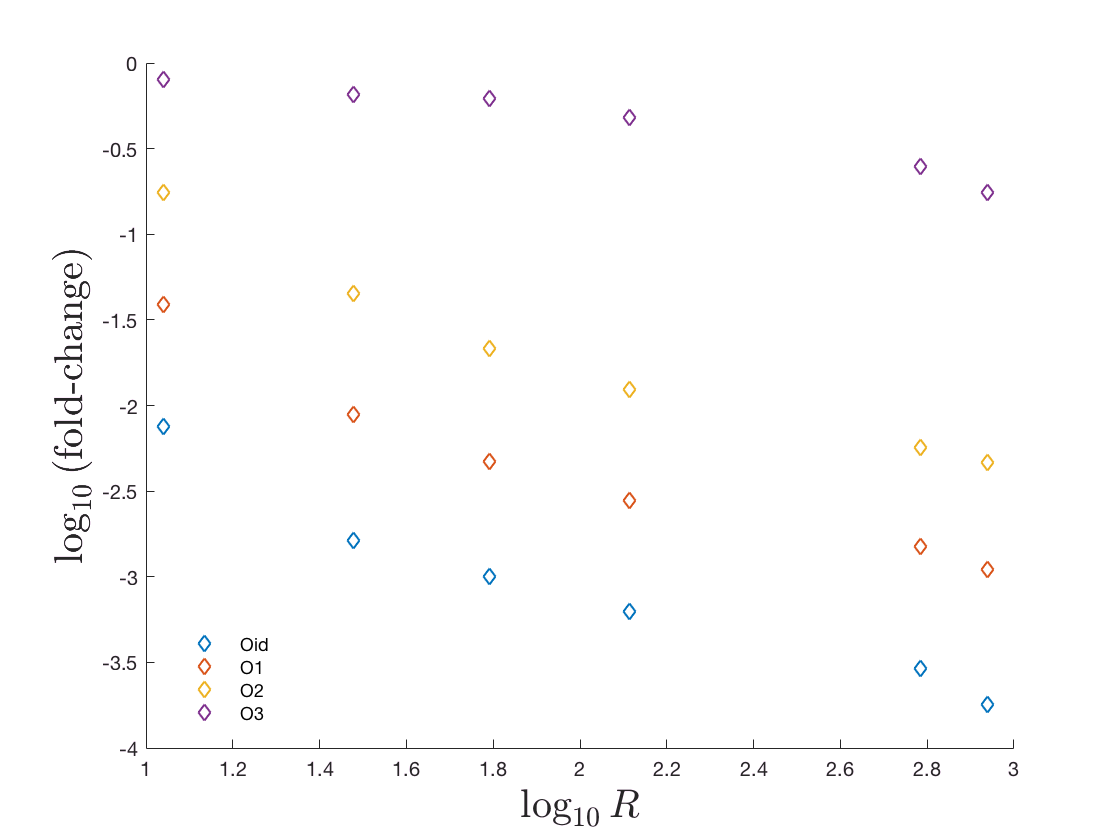

hold on
plot(log10(df.lacI), log10(df.Oid), 'd')
plot(log10(df.lacI), log10(df.O1), 'd')
plot(log10(df.lacI), log10(df.O2), 'd')
plot(log10(df.lacI), log10(df.O3), 'd')
xlabel('$\log_{10}R$', 'Interpreter', 'Latex', 'fontsize', 20)
ylabel('$\log_{10}\mbox{(fold-change)}$', 'Interpreter', 'Latex', 'fontsize', 20)
legend('Oid', 'O1', 'O2', 'O3', 'Location', 'southwest')
legend('boxoff')
hold off

# Introduction to Bayesian Regression

## This section is based on Justin Bois' fantastic [data analysis course](http://bebi103.caltech.edu/2015) at Caltech.

We highly recommend you to read his [introduction to bayesian parameter estimation](http://bebi103.caltech.edu/2015/lecture_notes/l02_parameter_estimation.pdf) to learn with more details what we will present here. Due to time constraints we will just go through a short primer on the topic.

As we mentioned during lecture for Bayesians probability is a *measure of plausibility* for any statement. For parameter estimation we want to find the probability distribution of the value of our parameters of interest, i.e. as Bayesians we will never say something like: "*this is the value of the parameter we measure in our experiment with 100% certainty*"; but rather we would report the **probability distribution** of the values that these parameters can take.

For example in our specific case we are interested in finding the value of the repressor binding energy $\Delta \varepsilon_r$ for the different operator sequences. We have **data** on the expression level fold-change for different copy number of repressors $R$. As derived in lecture and in [Garcia & Phillips 2011](http://www.rpgroup.caltech.edu/publications/Garcia2011c.pdf) the fold-change under the weak promoter approximation is given by


$$\mbox{fold-change} = \frac{1}{1 + \frac{2R}{N_{NS}}\mathbf{e}^{- \beta \Delta \varepsilon_r}},$$


where $N_{NS}$ is the number of non-specific binding sites for the repessor ($4.6\times10^6$ [E. coli's genome size](http://E. coli's genome size)) and $\beta$ is the inverse of the temperature times the Boltzmann constant.

Since the parameter we are trying to infer given some data is the binding energy, this can be written in terms of Bayes theorem as


$$P(\Delta \varepsilon_r \mid D, I) = \frac{P(D \mid \Delta \varepsilon_r, I)P(\Delta \varepsilon_r \mid I)}{P(D\mid I)},$$


where $D = \{ d_1, \ldots, d_n \}$ represents our data set, and $I$ represents **all** the previous information we have available. Recall that each term on Bayes theorem has a name commonly used in data analysis


$$\mbox{posterior} = \frac{\mbox{likelihood} \times \mbox{prior}}{\mbox{evidence}}.$$


But note that for our purposes of finding the **posterior probability** of the binding energy given the data the evidence doesn't depend on this parameter. So for this case it is just a normalization constant that we can ignore, giving us


$$P(\Delta \varepsilon_r \mid D, I) \propto P(D \mid \Delta \varepsilon_r, I)P(\Delta \varepsilon_r \mid I).$$


As researches we **have to make decisions** on what functional forms the likelihood and the prior will take. It is common to use a Gaussian prior given that the powerful [central limit theorem](https://en.wikipedia.org/wiki/Central_limit_theorem) tells us that processes which involve many subprocesses tend to be Gaussianly distributed (we are giving a very superficial explanation of this, for more information we highly recommend you [Sivia's outstanding book](http://www.amazon.com/Data-Analysis-Bayesian-Devinderjit-Sivia/dp/0198568320/ref=sr_1_1?ie=UTF8&qid=1452418747&sr=8-1&keywords=sivia+data+analysis)). Therefore assuming each data point is independent of the others our likelihood will be given by


$$P(D \mid \Delta \epsilon_r, \sigma, I) = \prod_{i \in D} \frac{1}{\sqrt{2 \pi \sigma^2}} \exp \left( \frac{ \left( \mbox{fc}_i - \mbox{fc(R_i, \Delta \varepsilon_r) \right)^2}{2 \sigma^2} \right),$$


where $i \in D$ means all the data points in our data set, $\mbox{fc_i}$is the $i^{th}$ experimentally measured fold-change for a strain with $R_i$repressors, and $\mbox{fc}(R_i, \Delta \varepsilon_r)$ is the equation we previously wrote for the theoretical fold-change as a function of the repressor copy number and the binding energy.

Notice that we added an **extra parameter** $\sigma$ for this Gaussian likelihood. This is a nuisance parameter that describes how the data deviates from the theoretical model; but since we are not interested on its actual value we can at the end integrate it out of our posterior probability.

The prior $P(\Delta \varepsilon_r, \sigma \mid I)$ that now also includes the extra parameter captures the information we knew about these parameters *before performing the experiment*. Without going too much into the details on how to properly choose the functional form of a prior we will assume for simplicity a so-called **uniform prior **for the binding energy, and a [Jeffreys prior](https://en.wikipedia.org/wiki/Jeffreys_prior) for the standard deviation $\sigma$. This means that we expect the energy to fall withing a reasonable range with equal probability for all values. Also we know that by definition the standard deviation cannot be negative. Mathematically this can be expressed as


$$P(\Delta \epsilon_r,\sigma \mid I) = P(\Delta \epsilon_r \mid I)\,P(\sigma \mid I) \propto \left\{
\begin{array}{cl}
\sigma^{-1} & \text{for }\Delta \epsilon_\mathrm{min} < \Delta \epsilon_r < \Delta \epsilon_r_\mathrm{max},\;\sigma > 0,\\
0 & \text{otherwise}.
\end{array}
\right.$$


Again we insist you read Justin's notes and Sivia's book to get more details on this selection of prior probabilities.

Putting our likelihood and our prior together, the posterior probability looks like


$$P(\Delta \varepsilon_r, \sigma \mid D, I) \propto \frac{1}{\sigma^{n+1}} \exp\left[ - \frac{1}{2\sigma^2} \sum_{i \in D} \left( \mbox{fc}_i - \mbox{fc(R_i, \Delta \varepsilon_r) \right)^2 \right].$$


We leave you as an exercise to show that this is in fact the functional form of the posterior probability.

To get rid of the nuisance parameter $\sigma
$ we can integrate it out as


$$P(\Delta \varepsilon_r \mid D, I) = \int d\sigma P(\Delta \varepsilon_r \sigma \mid D, I).$$


Performing this integral can be a very nasty task. Nevertheless it can be evaluated giving us a posterior of the form


$$P(\Delta \varepsilon_r \mid D, I) \propto \left( \sum_{i \in D} \left( \mbox{fc}_i - \mbox{fc(R_i, \Delta \varepsilon_r) \right)^2 \right)^{- \frac{n}{2}},$$


where $n \equiv |D|$ is the number of data points.

Many times when managing very small numbers (such as probabilities) is much easier to work with the log scales. In our example if we take the log of this posterior we find


$$\log P(\Delta \varepsilon_r \mid D, I) \propto- \frac{n}{2} \log \left( \sum_{i \in D} \left( \mbox{fc}_i - \mbox{fc(R_i, \Delta \varepsilon_r) \right)^2 \right)$$


Now that we have the theory in place we can just compute the posterior probability for the binding energy. Let us use $O_1$ as a first illustrative example. We have included a function `log_post `that contains this previous equation. The function takes three arguments:

- `epsilon`: . Repressor binding energy.

- `R_arr`: Number of repressors.

- `fc_arr`: Experimental fold-change measured for those given values of repressors.

We will compute the posterior probability for energies between -14 and -17 $k_BT$.

% Define energies to compute the posterior probability on.
energies = -17:0.01:-14;

% Initialize array to save the log posterior probability
log_posterior = zeros(1, length(energies));

% Loop through the energies computing the log probability at each step.
for i=1:length(log_posterior)
    log_posterior(i) = log_post(energies(i), df.lacI', df.O1');
end

We can now plot and see **the whole distribution!** This is part of the power of the Bayesian approach. We don't have to stare only at one fixed value for our parameter, but we can get a complete distribtion of the possible values that the parameter can take.

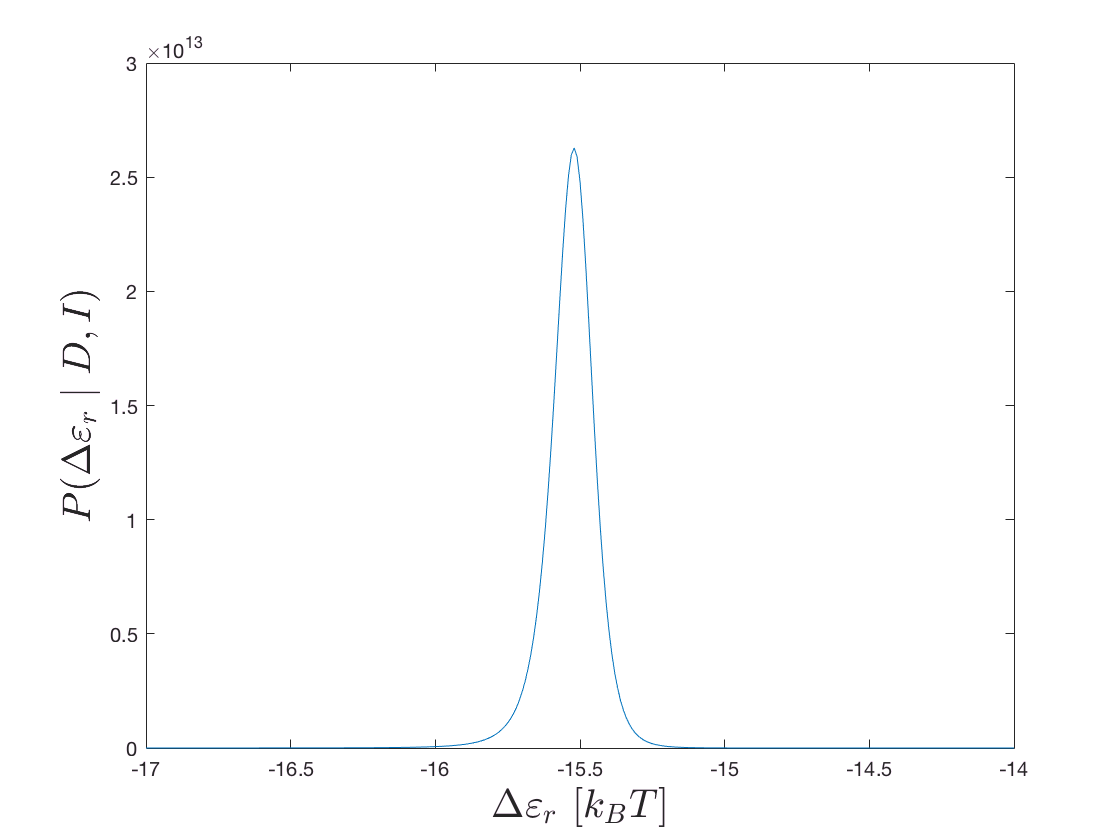

% Plot the energies vs probability
% remember to exponentiate since we computed the log posterior!
plot(energies, exp(log_posterior))

% Label the axis
xlabel('$\Delta \varepsilon_r$ $[k_BT]$', 'Interpreter', 'Latex', 'fontsize', 20)
ylabel('$P(\Delta \varepsilon_r \mid D, I)$', 'Interpreter', 'Latex', 'fontsize', 20)

Remember that the scale of the y axis is meaningless since we are not taking into account the normalization factor.

Even when we can plot the whole distribution sometimes it is good to report a "summary". For posterior distributions that are nicely behaved as it is in our case people use the so-called **Gaussian approximation **to report a mean and a variance for the parameter. 

This approximation consists of the following procedure: expand the logarithm of the posterior in a Taylor series around the maximum $\Delta \varepsilon_r^*$ up to second order. In our case that would be


$$\ln P(\Delta \varepsilon_r \mid D, I) \approx \ln P(\Delta \varepsilon_r^* \mid D, I)+ \frac{d^2}{d \Delta \varepsilon_r ^2} \ln P(\Delta \varepsilon_r^* \mid D, I) \bigg| _{\Delta \varepsilon_r ^*} (\Delta \varepsilon_r - \Delta \varepsilon_r ^*)^2,$$


where the first order derivative was equal to zero since the expansion was done around the global maximum.

If we exponentiate both sides of the equation we obtain


$$P(\Delta \varepsilon_r \mid D, I) = C \exp \left( \frac{d^2}{d \Delta \varepsilon_r^2} \ln P(\Delta \varepsilon_r \mid D, I) \bigg| _{\Delta \varepsilon_r^*} (\Delta \varepsilon_r - \Delta \varepsilon_r^*)^2 \right),$$


where $C$ is just a normalization constant. This is exactly the functional form of a **Gaussian distribution!** If this is not clear to you note that the variance $\sigma^2$ would be given by


$$\sigma^2 = - \frac{1}{2} \left( \frac{d^2}{d \Delta \varepsilon_r^2} \ln P(\Delta \varepsilon_r \mid D, I) \bigg| _{\Delta \varepsilon_r^*} \right)^{-1}.$$


Don't get lost with the math; this is indeed a very simple concept. Let us recapitulate once again what we just did:

From the log posterior probability we just performed a Taylor expansion around the maximum probability value, keeping up to the quadratic term. We then simply exponentiate this approximation finding out that what we end up with is a function that resembles a lot the Gaussian distribution where *the inverse of the second derivative with respect to the parameter plays the role of the ****variance***. 

The benefit of using a numerical environment such as Matlab is that we don't have to worry about evaluating these nasty derivatives. We can simply ask Matlab to first find the value of the energy that maximizes the posterior probability and then compute also numerically the second derivative around this point!

## Finding the energy that maximizes the posterior probability

Finding the parameter that maximizes our posterior probability amounts to an **optimization problem** in which we find the arguments (parameters) for which a function (the posterior distribution) is maximal. If we look at the form of the posterior, we see that the posterior is maximal when the sum


$$\sum_{i\in D} \left( fc_i - fc(R_i, \Delta \varepsilon_r) \right)^2$$


is minimal. So we need to find the value of $\Delta \varepsilon_r$ that minimizes this sum. For this we define a function call `resid` to compute this sum.

resid = @(epsilon) df.O1' - fc(df.lacI', epsilon);

Then we use the function `lsqnonlin `that uses the **Levenberg-Marquardt** to minimize the sum of the squares of a function. For this we must give an initial guess `epsilon_o` that we chose based on the plot of the posterior distribution.

% select initial guess for the algorithm
epsilon_o = -15;
% run the non linear optimization
epsilon_O1 = lsqnonlin(resid, epsilon_o);


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>




sprintf('energy with the max probability: %s kBT', epsilon_O1)

ans = energy with the max probability: -1.552064e+01 kBT

Once we have the local maximum we can compute the second derivative around this value using the `hessian` function.

syms e_r
fun = @(e_r) log_post(e_r, df.lacI', df.O1');
H = hessian(fun, e_r)

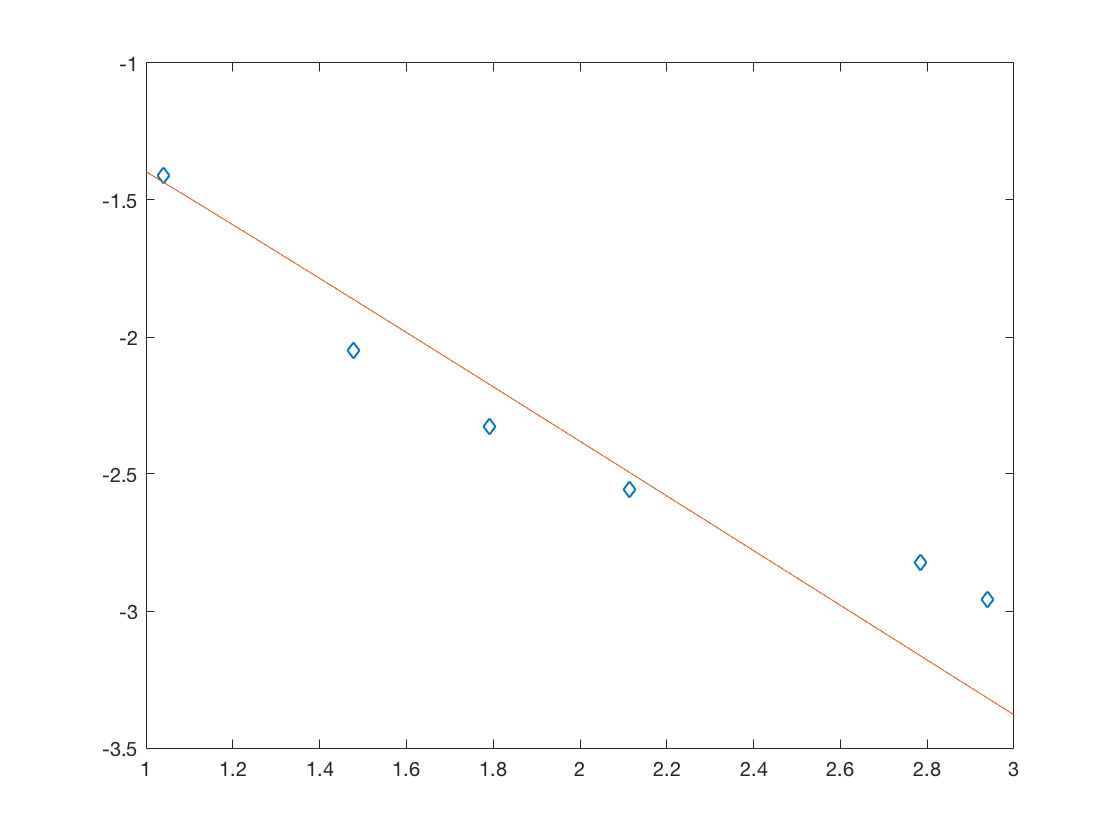

plot(log10(df.lacI), log10(df.O1), 'd')

hold on
plot(log10(10:1:1000), log10(fc(10:1:1000, epsilon_O1)))
hold off